# Plot (lateral, carsim)

参数

fontsize = 12;
labels = {'Original System', 'Identified System (cISSIM)', 'Identified System (SID)'};
filepath = 'D:\\OneDrive\\wyqy\\OneDrive\\学习\\!!!NOW!!!\\!!车辆仿真!!\\draft\\fig\\';

时域绘图

% 切分时间
timerange = 1:fix(0.05*length(ana_t));

函数或变量 'ana_t' 无法识别。


% 图窗
f = figure;
f.Units = 'centimeters'; f.Position = [0 0 14 10];

tiledlayout(2, 1, 'TileSpacing', 'tight', 'Padding', 'tight');

ax = afunc(1);
pfunc(t(timerange), ana_ori_yt(timerange, 1), '#0072BD', '-');
hold on;
pfunc(t(timerange), ana_ind_yt(timerange, 1), '#D95319', '-');
hold on;
pfunc(t(timerange), ana_sid_yt(timerange, 1), '#EDB120', '-');

title(ax, '\textbf{Lateral Speed} $\dot{y}$', 'Interpreter', 'latex', ...
    'FontName', 'Times New Roman', 'FontSize', fontsize, 'FontWeight', 'bold');
lfunc(labels);

ax = afunc(2);
pfunc(t(timerange), ana_ori_yt(timerange, 2), '#0072BD', '-');
hold on;
pfunc(t(timerange), ana_ind_yt(timerange, 2), '#D95319', '-');
hold on;
pfunc(t(timerange), ana_sid_yt(timerange, 2), '#EDB120', '-');
title(ax, '\textbf{Yaw Rate} $\dot{\psi}$', 'Interpreter', 'latex', ...
    'FontName', 'Times New Roman', 'FontSize', fontsize, 'FontWeight', 'bold');

% saveas(gcf, [filepath 'lateral_time_domain.eps'], 'epsc')

频域绘图

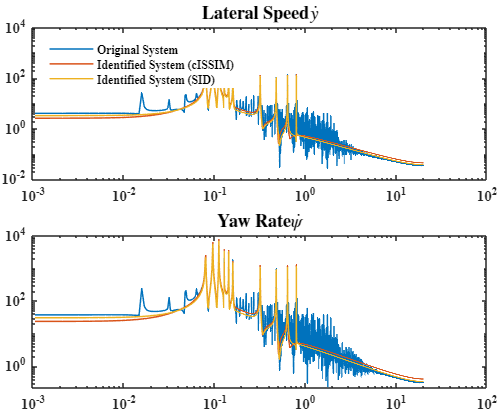

% 图窗
f = figure;
f.Units = 'centimeters'; f.Position = [0 0 12 10];

% 布局
tl = tiledlayout(2, 1, 'TileSpacing', 'tight', 'Padding', 'tight');

ax = afunc(1);
slfunc(ana_freq_ori_freq, ana_freq_ori_amp(:, 1), '#0072BD', '-');
hold on;
slfunc(ana_freq_ori_freq, ana_freq_ind_amp(:, 1), '#D95319', '-');
hold on;
slfunc(ana_freq_ori_freq, ana_freq_sid_amp(:, 1), '#EDB120', '-');
title(ax, '\textbf{Lateral Speed} $\dot{y}$', 'Interpreter', 'latex', ...
    'FontName', 'Times New Roman', 'FontSize', fontsize, 'FontWeight', 'bold');
lfunc(labels);

ax = afunc(2);
slfunc(ana_freq_ori_freq, ana_freq_ori_amp(:, 2), '#0072BD', '-');
hold on;
slfunc(ana_freq_ori_freq, ana_freq_ind_amp(:, 2), '#D95319', '-');
hold on;
slfunc(ana_freq_ori_freq, ana_freq_sid_amp(:, 2), '#EDB120', '-');
title(ax, '\textbf{Yaw Rate} $\dot{\psi}$', 'Interpreter', 'latex', ...
    'FontName', 'Times New Roman', 'FontSize', fontsize, 'FontWeight', 'bold');


% saveas(gcf, [filepath 'lateral_freq_domain.eps'], 'epsc')

函数

function ax = afunc(t)
    ax = nexttile(t);
    % set(gca, 'FontName', 'Times New Roman', 'FontSize', 12, 'FontWeight', 'bold');
end
function pfunc(x, y, color, linestyle)
    plot(x, y, 'Color', color, 'LineStyle', linestyle, 'LineWidth', 1);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10, 'FontWeight', 'bold');
end
function slfunc(x, y, color, linestyle)
    loglog(x, y, 'Color', color, 'LineStyle', linestyle, 'LineWidth', 1);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10, 'FontWeight', 'bold');
end
function lfunc(texts)
    lgd = legend(texts, 'FontName', 'Times New Roman', 'FontSize', 8, 'FontWeight', 'bold');
    lgd.Location = 'northwest'; lgd.Box = 'off';
end